# UAVのホバリング Part 2: 積分器、微分器の拡張

## アクチュエータの限界

[Part 1](matlab:open('UHG_control_UAV_p1.mlx'))で用いたUAVのプラントモデル、及び制御器は、数学的に理想的な線形モデルであるため、適切にゲインチューニングを行うことで、どれ程厳しい制御目的でも満たすことが可能である。しかし、そのようなモデルは、現実世界には存在し得ない。現実世界のシステムには、多かれ少なかれ「非線形要素」を含んでいるためである。線形、非線形の違いについては、～～にて詳細に説明している。ここでは、その非線形の例として、アクチュエータに上下限がある場合を考える。

プラントモデルを詳細にしていくと、Fig.1のように、「アクチュエータ」と「プロセス」に分解することができる。

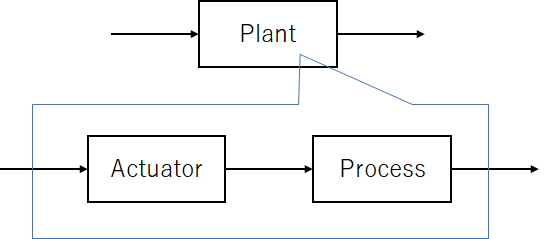

Fig.1 プラントモデルの詳細

アクチュエータとは、信号を実際の力やエネルギーに変換し、システムに変化を与える装置である（例えば、モーターやヒーターなど）。プロセスとは、アクチュエータが影響を与える対象である。今回のマルチコプターのプラントモデルであれば、アクチュエータはモーターとプロペラであり、プロセスは機体である。

マルチコプターで用いられるモーターは、ブラシレスDCモーターが一般的である。ブラシレスDCモーターは、それを制御するインバータ装置とセットで用いられる。インバータ装置はPWM信号を受け取り、その値に比例した回転速度でモーターを回転させる。厳密には、回転速度と推力の関係は非線形であるため、この点においても、制御性能の改善点として考慮する余地があるが、本節では、PWM信号の上下限についてのみ検討する。

PWMとは何か、については、「[モーター制御 Part3: PWM（パルス幅変調）によるブラシレスDCモーターの速度制御](https://www.youtube.com/watch?v=b5J5qkR7msc)」にて詳細に説明している。ここでは、PWMは割合であり、0から1まで（もしくは0%から100%まで）の値しか取らない、ということが分かっていればよい。

## ワインドアップ

アクチュエータに上下限がある場合の制御課題について検討したい。ここで、[Part 1](matlab:open('UHG_control_UAV_p1.mlx'))で用いたプラントモデルの入力部分に、0から2000rpmまでの飽和処理を追加してみる。'UHG_PID_control_2.slx'を開き、プラントモデルを確認すること。

model_name = 'UHG_PID_control_2';
open_system(model_name);

また、ここでは応答の違いを分かりやすくするため、PIDゲインをそれぞれ、100, 30, 0に設定している。

モデルを実行して動作を確認する。

sim(model_name);
UHG_PID_control_2_plot_in_SDI;

実行結果をFig.2に示す。制御開始直後に、大きなオーバーシュートが発生していることが分かる。

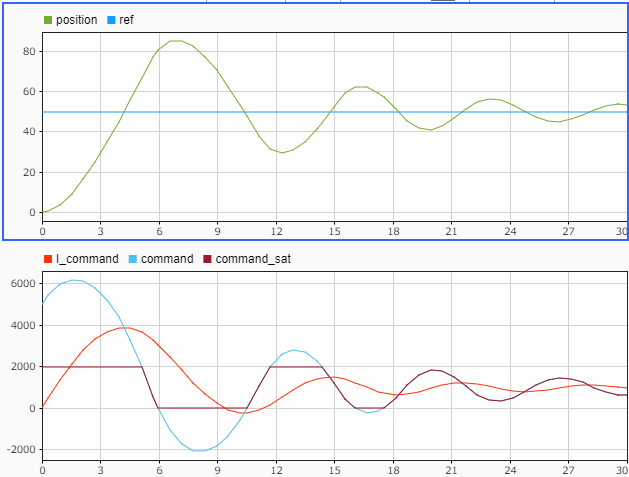

Fig.2 飽和を含むプラントモデルを制御した結果

'I_command'は積分器の出力、'command'はPID制御器の出力（操作量）、'command_sat'は操作量をアクチュエータ上下限で飽和させた値である。シミュレーション開始時、偏差は50であるため、積分器は高速に立ち上がる。偏差が0になるまで積分器出力は増加を続け、4秒時に偏差がマイナスになって初めて減少に転ずる。しかしその後、5.5秒に減速に転じる操作量となるまで、機体の速度は減少を開始しない。このように、積分器がアクチュエータの上下限を超えて積分保持量を持つことによって、過剰なオーバーシュートが発生する現象を「ワインドアップ」と呼ぶ。

### Task 1

必要であれば、比例器の出力をグラフに追加し、比例器と積分器の動作の違いを確認すること。

上記の例では、積分ゲインが大きい場合に発生しうる例であるが、積分ゲインの大きさに関係なく発生する場合もある。例えば、マルチコプターが飛び立とうとしている時に、手で抑えて飛ばないようにしていた、という場合にも、ワインドアップ現象は発生する。

そのような状況を'UHG_PID_control_2s.slx'にて再現した。モデルを実行し、動作を確認すること。

model_name = 'UHG_PID_control_2s';
open_system(model_name);
sim(model_name);
UHG_PID_control_2_plot_in_SDI;

## アンチワインドアップ制御

ワインドアップ現象を抑制する方法としては、アクチュエータの飽和に至る操作量になる場合に、積分保持量を操作し、上限を超えて増加し続けないようにすることが考えられる。この手法を「アンチワインドアップ」と呼ぶ。

'UHG_PID_control_2_Anti.slx'にて、アンチワインドアップを実装したPID制御器を実装した。モデルを開いて確認すること。

model_name = 'UHG_PID_control_2_Anti';
open_system(model_name);

ここでは、Simulinkの標準ライブラリの「PID Controller」ブロックを用いた。「PID Controller」ブロックは、ブロックパラメータの「出力の飽和」タブにて、飽和上下限値とアンチワインドアップの手法を設定することができる。

アンチワインドアップの手法の詳細については、「[アンチワインドアップのアルゴリズム](matlab:open('AWU_anti_windup'))」にて説明している。

モデルを実行して結果を確認する。

sim(model_name);
UHG_PID_control_2a_plot_in_SDI;

実行結果をFig.3に示す。

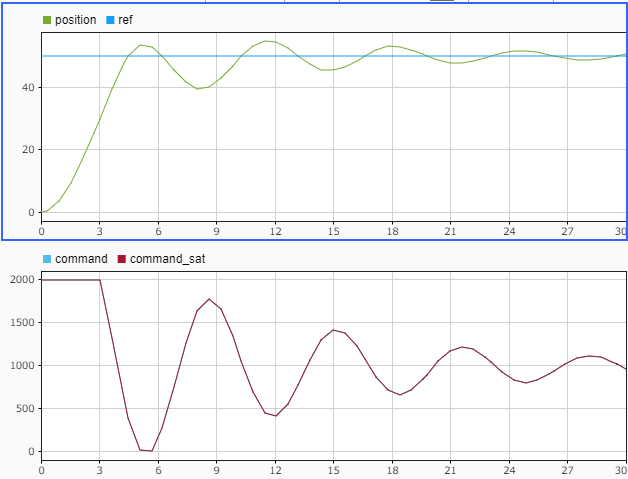

Fig.3 アンチワインドアップを用いて制御した結果

Fig.2と比較して、オーバーシュートが大幅に軽減されていることが分かる。

## ノイズ

制御器はプロセスの変動を計測し、次の操作量を計算している。この観点からプロセスを分解すると、Fig.4のように表すことができる。

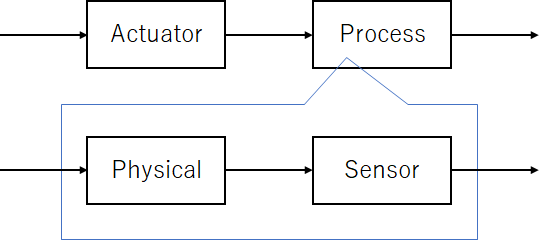

Fig.4 プロセスの詳細

制御対象のシステムで発生した物理現象は、センサーによって計測され、信号に変換されている。しかし、現実世界のセンサーには、様々な非線形要素、または「ノイズ」を含む。ノイズが発生する理由は、現実世界には様々な事象（外乱）が発生しており、それらを十分に取り除いて物理量を計測することができないためである。

ノイズが制御器に与える悪影響については、「[微分器とノイズの関係](matlab:open('DFN_differentiator_and_noise.mlx'))」にて詳細に説明している。ここでは、ノイズは微分器にて増幅されるため、操作量を過剰に増減させる現象が発生する、ということが分かっていればよい。

ノイズを含むプラントモデルの制御課題について検討したい。'UHG_PID_control_3.slx'にて、プラントモデルのセンサーにノイズを含んだ状態を再現した。モデルを開いて確認すること。

model_name = 'UHG_PID_control_3';
open_system(model_name);

'Plant_model'サブシステム内で、position信号に「Random Number」ブロックからの信号を加算している。「Random Number」ブロックは平均0、分散1の正規分布乱数を生成している。また、前節で説明したアクチュエータの飽和も合わせて実装している。

ゲインは、[Part 1](matlab:open('UHG_control_UAV_p1.mlx'))と同じくPゲイン100、Iゲイン10、Dゲイン100としている。

モデルを実行し、結果を確認する。

sim(model_name);
UHG_PID_control_2a_plot_in_SDI;

指令値が極端に大きく増減していることがわかる。ここで、グラフを拡大し、'command'と'command_sat'を比較する。Fig.5にその結果を示す。

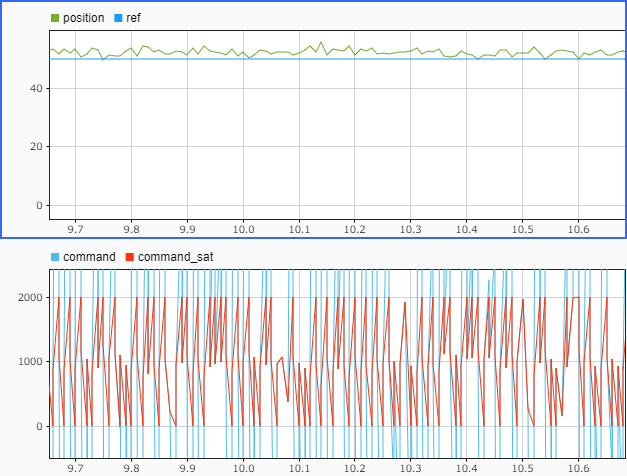

Fig.5 ノイズを含むプラントモデルを制御した結果

'command'がアクチュエータの飽和上下限を超えて振動しているため、'command_sat'が0と2000を頻繁に行き来していることがわかる。全体を見れば、高さは指令値通り50m地点で定常状態に至っており、制御目的は達成している。しかし、アクチュエータには非常に大きい指令値変動が加わっており、このような入力は、少なからずアクチュエータの寿命を縮めてしまう。また、今回のマルチコプターは積分型のシステムであるために問題になっていないが、比例型のシステムでは、ノイズを増幅して発散に至る可能性もある。

ノイズで発散に至る現象については、「[微分器とノイズの関係](matlab:open('DFN_differentiator_and_noise.mlx'))」にて詳細に説明している。

## ローパスフィルター

このようなノイズによる悪影響は、微分器にローパスフィルターをかけることで抑制できる。'UHG_PID_control_3f.slx'にて、ローパスフィルターを適用したモデルを構築した。

model_name = 'UHG_PID_control_3f';
open_system(model_name);

ここでは、Simulinkの標準ライブラリの「PID Controller」ブロックを用いた。「PID Controller」ブロックは、デフォルトの設定で微分器にローパスフィルターをかけるようになっており、ブロックパラメータの「フィルター係数(N)」にて、そのフィルターのカットオフ周波数を設定できる。フィルター係数は3に設定している。

モデルを実行し、結果を確認する。

sim(model_name);
UHG_PID_control_2a_plot_in_SDI;

Fig.6にその結果を示す。

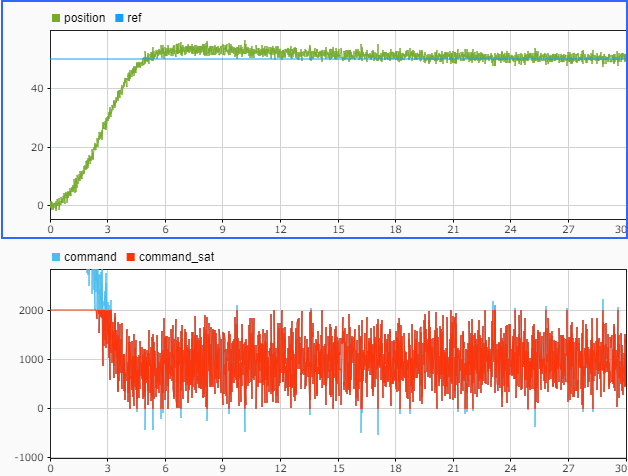

Fig.6 微分器にローパスフィルターをかけた場合の実行結果

'command'の大きな変動を抑制し、ほとんどの場合でアクチュエータの上下限以内に抑えることができている。

ここで注意する所としては、信号にノイズが多く含まれる場合には、制御性能を十分に上げることができない場合もある、という点である。ローパスフィルターをかけると高周波成分の位相が遅れるため、高速な制御応答を目標としている場合には、その位相の遅れの影響が無視できず、目標を達成する前に振動、発散してしまうことがある。

この現象の程度は、信号とノイズの比率（S/N比）に依存する。ノイズの比率が大きい程、システムの実現可能な制御性能の幅が小さくなる。制御性能を向上させる場合には、制御アルゴリズムだけでなく、センサーの精度についても評価するなど、システム全体で改善方法を考えることも大切である。

[（PID制御とは）戻る](matlab:(proceed_live_page('UHG_control_UAV_p1.mlx')))　|　[進む（Part 3: ゲインチューニング）](matlab:(proceed_live_page('UHG_control_UAV_p3.mlx')))

*Copyright 2021 The MathWorks, Inc.*